# DoE Generator 

# Live Script

## Create structure listing identification parameters

clear;
clc;

F(1).Units = "[W/m/K]";
F(1).Name = "k_d";
F(1).Fixed = false;                 % Distributed parameter
F(1).Lo = 0;   
F(1).Hi = 0.4;
F(1).Sz = 7;
F(2).Name = "rho_d";
F(2).Units = "[kg/m^3]";
F(2).Fixed = false;                 % Distributed parameter
F(2).Lo = 0.5;
F(2).Hi = 100;
F(2).Sz = 10;
F(3).Name = "Ks";
F(3).Units = "";
F(3).Fixed = true;                  % Fixed parameter
F(3).Lo = 0.001;
F(3).Hi = 0.999;
F(3).Sz = 1;

##  Create SobolSequence object and generate experiment

Sobj = SobolSequence( F, "M", 3, "K", 3 );                   % Quadratic B-spline with 3 knots for distributed parameters
Sobj = Sobj.generate( 11, "Scramble", true, "Con", true );   % Design size is 11 points and sequence is scrambled.

## Generate the DoEhook object connecting the BO and ECOMO model objects

H = DoEhook();
H = H.addDesignAvailableListener( Sobj );   % Add listener for the design available event
Sobj.export();                              % Generate the parameter table

## Generate the ECOMO interface object & run the experiment

E = ecomoInterface();
E = E.loadIdentificationData();
E = E.addRunExperimentListener( H );
H.runSimulation();

new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 10

## Generate diagnostic plots

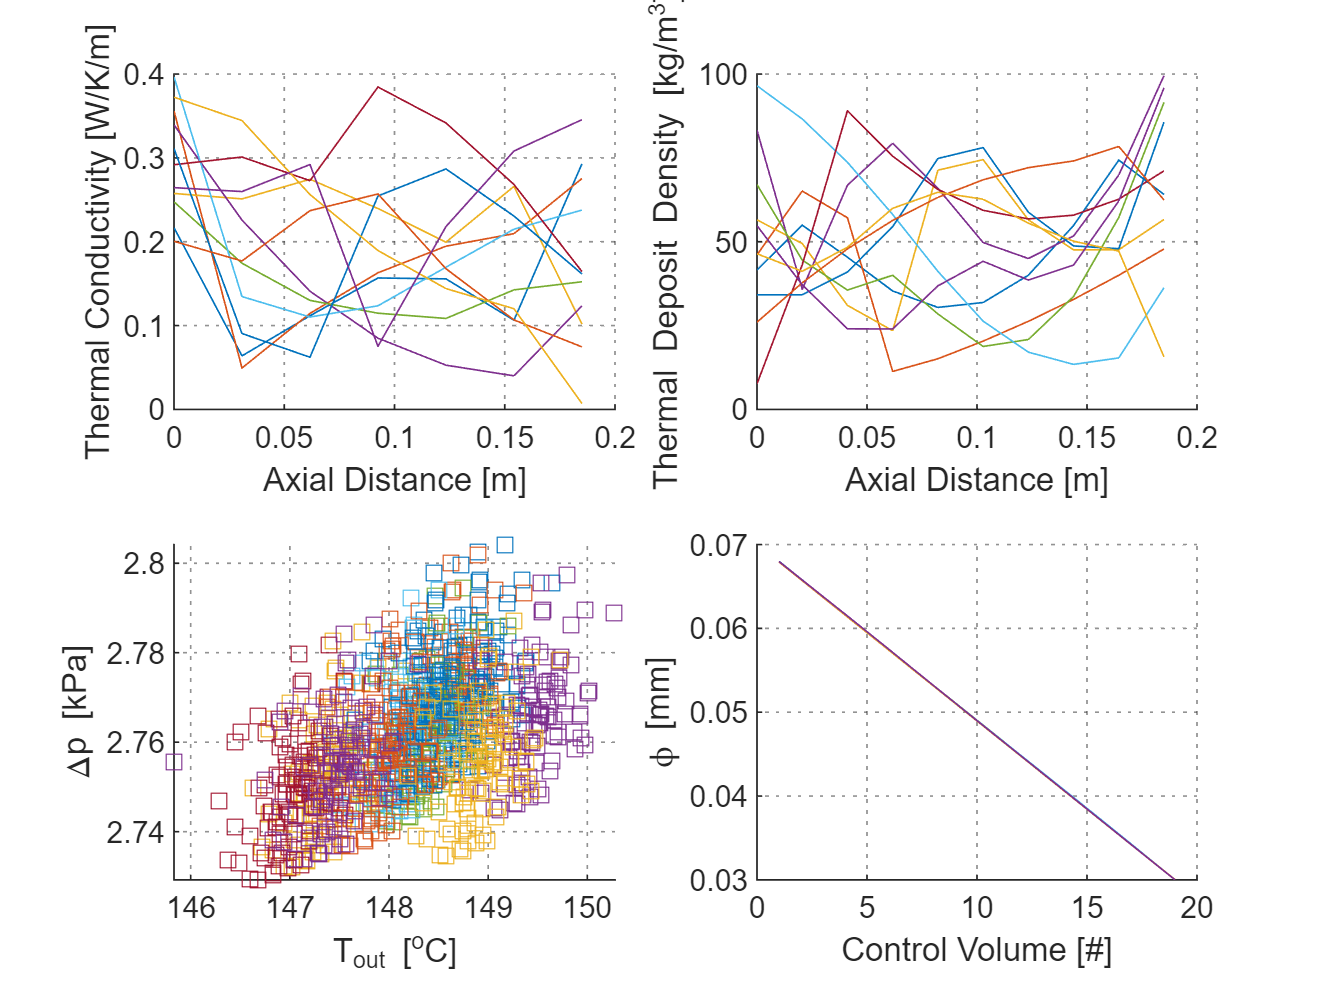

N = Sobj.NumPoints;
figure;
for Q = 1:4
    Ax( Q ) = subplot(2,2,Q);  %#ok<*SAGROW> 
    Ax( Q ).NextPlot = "add";
    grid on;
    Ax( Q ).GridAlpha = 0.5;
    Ax( Q ).GridLineStyle = ":";
end
for Q = 1:N
    plot( Ax( 1 ), E.FM(Q).ModelPara.k_d(:,1), E.FM(Q).ModelPara.k_d(:,2), '-' );     % Thermal conductivity
    plot( Ax( 2 ), E.FM(Q).ModelPara.rho_d(:,1), E.FM(Q).ModelPara.rho_d(:,2), '-');  % Deposit density
    plot( Ax( 3 ), E.FM(Q).T_out_L_degC, E.FM(Q).deltaPre_L_kPa, 's' );               % Temperature out versus delta pressure
    plot( Ax( 4 ), 1000 * E.FM( Q ).phi_soot_tn1, '-' );                              % Deposit thickness
end
xlabel( Ax( 1 ), "Axial Distance [m]");
ylabel( Ax( 1 ), "Thermal Conductivity [W/K/m]");
xlabel( Ax( 2 ), "Axial Distance [m]");
ylabel( Ax( 2 ), "Thermal Deposit Density [kg/m^3]");
xlabel( Ax( 3 ), "T_{out} [^oC]");
ylabel( Ax( 3 ), "\Deltap [kPa]")
xlabel( Ax( 4 ), "Control Volume [#]");
ylabel( Ax( 4 ), "\phi [mm]")